# Chapter 1: Calibration of Output Devices

%% 1. Load Necessary Data
clear; clc; close all;

% Load spectral data, illuminants, and color matching functions
load('chips20.mat');  % Spectral reflectance data
load('illum.mat');    % Spectral data for different illuminants
load('xyz.mat');      % Color Matching Functions (CMFs)
load('TRC_display.mat'); % Tone reproduction curves for display
load('DLP.mat');      % Spectral data for DLP projector primaries

% Define wavelength range (400:5:700 nm → 61 elements)
wavelengths = 400:5:700; 

## 1.1: Plot TRCs (Tone-Reproduction Curves) for RGB channels

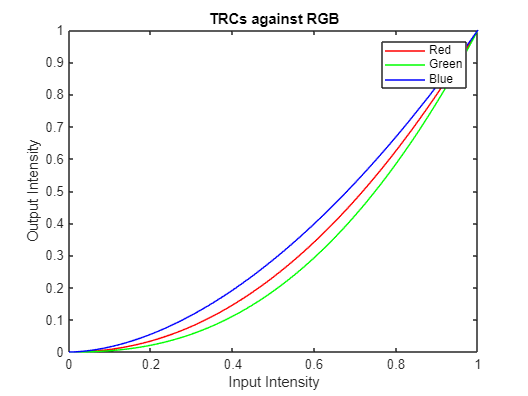

% Tone Reproduction curves show the relationship between luminence and
% color and display luminance
figure;
plot(0:0.01:1, TRCr, 'r', 0:0.01:1, TRCg, 'g', 0:0.01:1, TRCb, 'b');
title('Tone Reproduction Curves (TRCs)');
xlabel('Input Intensity');
ylabel('Output Intensity');
title('TRCs against RGB');
legend('Red', 'Green', 'Blue');

## 1.2: Linearization using interpolation (Check hints for inverse interpolation)

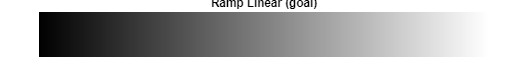

% Load images
load('Ramp_linear.mat');
load('Ramp_display.mat');

% Show Ramp_linear
figure;
imshow(Ramp_linear);
title('Ramp Linear (goal)');

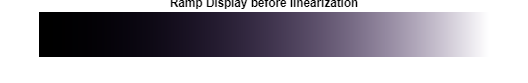


% Show Ramp_display before linearization
figure;
imshow(Ramp_display);
title('Ramp Display before linearization');

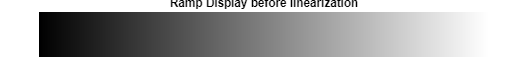


% linearization to image
Ramp_linearized(:,:,1) = interp1(TRCr, 0:0.01:1, Ramp_display(:,:,1), 'pchip'); % interploation from tips
Ramp_linearized(:,:,2) = interp1(TRCg, 0:0.01:1, Ramp_display(:,:,2), 'pchip');
Ramp_linearized(:,:,3) = interp1(TRCb, 0:0.01:1, Ramp_display(:,:,3), 'pchip');

% Display linearized image
figure;
imshow(Ramp_linearized);
title('Ramp Display before linearization');

## 1.3: Gamma correction

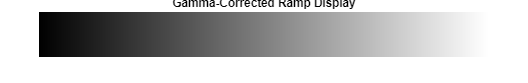

% Define gamma
gamma_R = 2.1; 
gamma_G = 2.4;
gamma_B = 1.8;

% Gamma correction using eq 4, can't make Dmax work
Ramp_gamma_corrected(:,:,1) = Ramp_display(:,:,1) .^ (1/gamma_R);
Ramp_gamma_corrected(:,:,2) = Ramp_display(:,:,2) .^ (1/gamma_G);
Ramp_gamma_corrected(:,:,3) = Ramp_display(:,:,3) .^ (1/gamma_B);

% Display the gamma-corrected image
figure;
imshow(Ramp_gamma_corrected);
title('Gamma-Corrected Ramp Display');

# Chapter 2: Spectral Forward Model of the Output Device

## 2.1: Load and plot spectral data for DLP projector

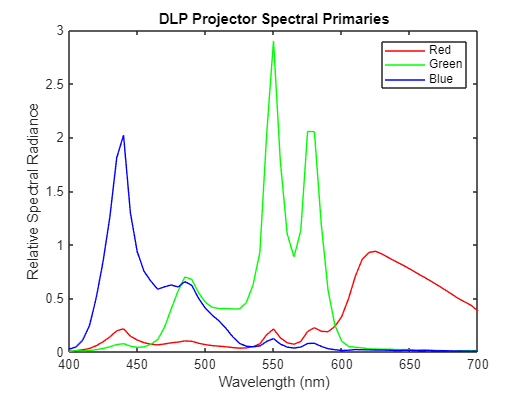

figure;
plot(wavelengths, DLP(:,1), 'r', wavelengths, DLP(:,2), 'g', wavelengths, DLP(:,3), 'b');
title('DLP Projector Spectral Primaries');
xlabel('Wavelength (nm)');
ylabel('Relative Spectral Radiance');
legend('Red', 'Green', 'Blue');

## 2.2: Compute spectral output for raw camera data

load('RGB_raw.mat'); % Raw RGB data

% Compute projected spectra
SRGB = DLP * RGB_raw; % Eq. (2)

% Convert to XYZ
k = 100 / sum(xyz(:,2)); % Normalization factor
XYZ_projected = k * (xyz' * SRGB);

% Compute color difference (delta Eab)
XYZ_ref = k * (xyz' * chips20'); % Reference XYZ
LAB_ref = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:));
LAB_projected = xyz2lab(XYZ_projected(1,:), XYZ_projected(2,:), XYZ_projected(3,:));
deltaE_raw = sqrt(sum((LAB_projected - LAB_ref).^2, 1));

fprintf('Mean delta Eab (Raw Camera Input to Projector): %.2f\n', mean(deltaE_raw));

Mean delta Eab (Raw Camera Input to Projector): 9.22


fprintf('Max delta Eab: %.2f\n', max(deltaE_raw));

Max delta Eab: 19.30


## 2.3: Compute spectral output for calibrated camera data

load('RGB_cal.mat'); % Raw RGB data

% Compute projected spectra with calibrated RGB
SRGB_calibrated = DLP * RGB_cal;

% Convert to XYZ
XYZ_projected_calibrated = k * (xyz' * SRGB_calibrated);
LAB_projected_calibrated = xyz2lab(XYZ_projected_calibrated(1,:), XYZ_projected_calibrated(2,:), XYZ_projected_calibrated(3,:));

% Compute delta Eab color difference
deltaE_calibrated = sqrt(sum((LAB_projected_calibrated - LAB_ref).^2, 1));

fprintf('Mean delta Eab (Calibrated Camera Input to Projector): %.2f\n', mean(deltaE_calibrated));

Mean delta Eab (Calibrated Camera Input to Projector): 4.91


fprintf('Max delta Eab: %.2f\n', max(deltaE_calibrated));

Max delta Eab: 14.00


# Chapter 3: Inverse Characterization of the Output Device

## 3.1: Compute XYZ Values for Projector Primaries

XYZ_R = k * (xyz' * DLP(:,1));
XYZ_G = k * (xyz' * DLP(:,2));
XYZ_B = k * (xyz' * DLP(:,3));
ACRT = [XYZ_R, XYZ_G, XYZ_B]; % Eq. (3)

% Compute inverse transformation matrix
ACRT_inv = inv(ACRT);

## 3.2: Full Color Management Workflow

load('RGB_cal_D65_cam1.mat'); % Load calibrated camera data from Lab 1 section 3.4 & 3.5??
XYZ_input = (ACRT_inv * RGB_cal_D65_cam1')'; % Corrected matrix multiplication

% Convert XYZ to projector RGB
RGB_projector = (ACRT_inv * XYZ_input')';

% Compute final projected spectra
SRGB_projected = DLP * RGB_projector';

% Convert to XYZ
XYZ_projected_final = k * (xyz' * SRGB_projected);
LAB_projected_final = xyz2lab(XYZ_projected_final(1,:), XYZ_projected_final(2,:), XYZ_projected_final(3,:));

% Compute delta Eab
deltaE_final = sqrt(sum((LAB_projected_final - LAB_ref).^2, 1));

disp("Final Color Managed Output")

Final Color Managed Output


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_final));

Mean delta Eab: 56.90


fprintf('Max delta Eab: %.2f\n', max(deltaE_final));

Max delta Eab: 86.14


## 3.3: Analyze Projector RGB Values (D'R, D'G, D'B)

% Check if any values are out of bounds
disp("Display RGB projector")

Display RGB projector


disp(RGB_projector)

   1.0e-03 *

    0.1598    0.0098    0.0288
    0.2026   -0.0431    0.0062
   -0.0409    0.0216    0.0147
   -0.0122    0.0178    0.0173
   -0.7309    0.2794    0.0924
   -0.2554    0.1126    0.0499
    0.4178   -0.0706   -0.0405
    0.0510   -0.0107    0.0008
    0.2749   -0.0519   -0.0283
    0.0093    0.0010    0.0024
    0.2749   -0.0781   -0.0074
    0.2973   -0.0790   -0.0167
    0.1636   -0.0420   -0.0041
   -0.1312    0.0654    0.0085
   -0.3751    0.1479    0.0839
    0.1626   -0.0432    0.0027
   -0.6851    0.2500    0.0980
    0.3492   -0.0948   -0.0250
    0.2360   -0.0019   -0.0214
   -0.0213    0.0396    0.0285



out_of_bounds = (RGB_projector < 0) | (RGB_projector > 1);

% Display the number of out-of-range values
num_out_of_bounds = sum(out_of_bounds(:));
fprintf('Number of out-of-bounds RGB values: %d\n', num_out_of_bounds);% If not 0, some are out of bounds?

Number of out-of-bounds RGB values: 25


## 3.4: Clip RGB Values to [0,1] Range

% Clip RGB Values to [0,1] Range
RGB_projector_clipped = min(max(RGB_projector, 0), 1);

% Compute final output spectra with clipped values, like 3.2
SRGB_clipped = DLP * RGB_projector_clipped';
XYZ_projected_clipped = k * (xyz' * SRGB_clipped);
LAB_projected_clipped = xyz2lab(XYZ_projected_clipped(1,:), XYZ_projected_clipped(2,:), XYZ_projected_clipped(3,:));

% Compute new delta Eab after clipping
deltaE_clipped = sqrt(sum((LAB_projected_clipped - LAB_ref).^2, 1));

disp("After Clipping RGB to [0,1]")

After Clipping RGB to [0,1]


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_clipped));

Mean delta Eab: 56.86


fprintf('Max delta Eab: %.2f\n', max(deltaE_clipped));

Max delta Eab: 86.14



% Same max but diffrent mean comparing 3.2

## 3.5: Compare Projector Gamut with sRGB

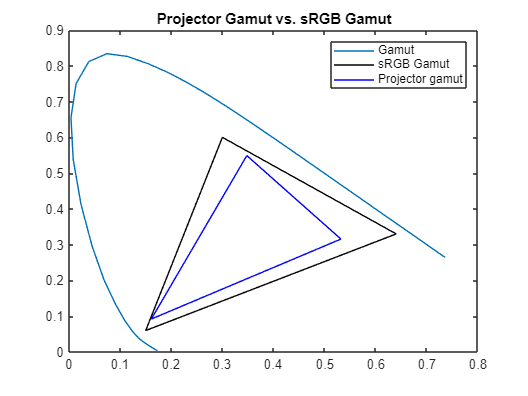

% Gamut = the complete range or scope of something, aka color in this case (färgomfång) 
figure;
plot_chrom_sRGB(ACRT);
legend('Gamut', 'sRGB Gamut', 'Projector gamut');
title('Projector Gamut vs. sRGB Gamut');

% Projector has smaller gamut that all off SRGB, espehially in the red
% range as expected in 2.1

## 3.6 Chromaticity Analysis of a Reproduced Color Sample

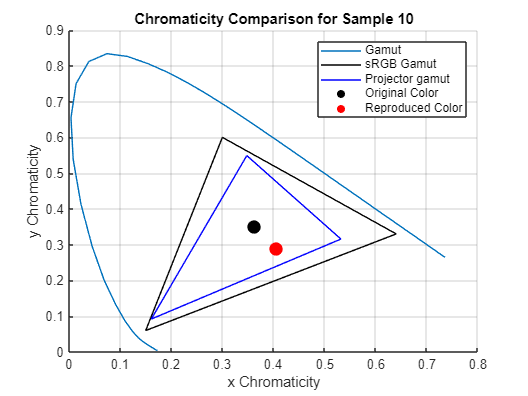

% Sample with a low delta Eab in whatever column of matrix (important,
% matrix not vector)
[~, best_sample_idx] = min(deltaE_clipped); 

% Extract XYZ values for the original and reproduced color
XYZ_original = XYZ_ref(:, best_sample_idx);
XYZ_reproduced = XYZ_projected_clipped(:, best_sample_idx);

% Convert to xy chromaticity coordinates
xy_original = XYZ_original(1:2) / sum(XYZ_original);
xy_reproduced = XYZ_reproduced(1:2) / sum(XYZ_reproduced);

% Plot chromaticity coordinates
figure;
hold on;
plot_chrom_sRGB(ACRT); % Display projector gamut
% Enter scatterplot elements (dots)
scatter(xy_original(1), xy_original(2), 100, 'k', 'filled'); % Original color
scatter(xy_reproduced(1), xy_reproduced(2), 100, 'r', 'filled'); % Reproduced color
legend('Gamut', 'sRGB Gamut', 'Projector gamut' , 'Original Color', 'Reproduced Color');
title(sprintf('Chromaticity Comparison for Sample %d', best_sample_idx));
xlabel('x Chromaticity');
ylabel('y Chromaticity');
grid on;
hold off;


% Display numerical chromaticity values (coordinates) & diffrences
fprintf('Chromaticity (xy) of Original Sample %d: (%.3f, %.3f)\n', best_sample_idx, xy_original(1), xy_original(2));

Chromaticity (xy) of Original Sample 10: (0.362, 0.351)


fprintf('Chromaticity (xy) of Reproduced Sample %d: (%.3f, %.3f)\n', best_sample_idx, xy_reproduced(1), xy_reproduced(2));

Chromaticity (xy) of Reproduced Sample 10: (0.406, 0.290)


fprintf('Perceptual color difference delta Eab: %.2f\n', deltaE_clipped(best_sample_idx));

Perceptual color difference delta Eab: 25.46
